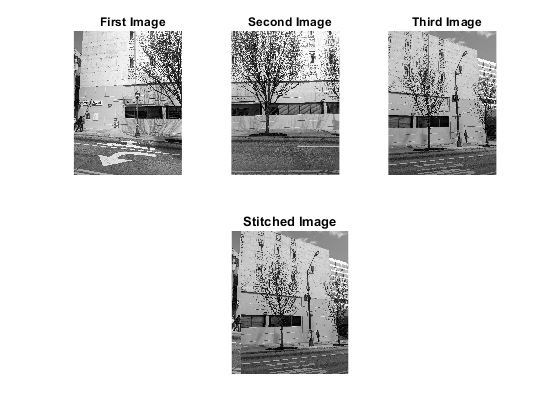

clc;
clear all;
close all;
F = imread("C:\Users\Sahithi Kolla\Downloads\GSU_Building_Database-20220430T185051Z-001\GSU_Building_Database\studentcenterwest1.jpg");
S = imread("C:\Users\Sahithi Kolla\Downloads\GSU_Building_Database-20220430T185051Z-001\GSU_Building_Database\studentcenterwest2.jpg");
V = imread("C:\Users\Sahithi Kolla\Downloads\GSU_Building_Database-20220430T185051Z-001\GSU_Building_Database\studentcenterwest3.jpg");

%Converting color images to Grayscale
F = im2double(rgb2gray(F));
S = im2double(rgb2gray(S));
V = im2double(rgb2gray(V));
[rows cols] = size(F);
Tmp = [];
Tmp1 = [];
temp = 0;
% Saving the patch(rows x 5 columns) of second(S) & third(V) images in    
% S1 & V1 resp for future use.
for i = 1:rows
    for j = 1:5
        S1(i,j) = S(i,j);
        V1(i,j) = V(i,j);
    end
end
% Performing Correlation i.e. Comparing the (rows x 5 column) patch of 
% first image with patch of second image i.e. S1 saved earlier.
for k = 0:cols-5 % (cols - 5) prevents j from going beyond boundary of image.
    for j = 1:5
        F1(:,j) = F(:,k+j);% Forming patch of rows x 5 each time till cols-5.
    end
    temp = corr2(F1,S1);% comparing the patches using correlation.
    Tmp = [Tmp temp]; % Tmp keeps growing, forming a matrix of 1*cols
    temp = 0;
end
[Min_value, Index] = max(Tmp);% Gets the Index with maximum value from Tmp.
% Determining the number of columns of new image. Rows remain the same.
n_cols = Index + cols - 1;
Opimg = [];
for i = 1:rows
    for j = 1:Index-1
        Opimg(i,j) = F(i,j);% First image is pasted till Index.
    end
    for k = Index:n_cols
        Opimg(i,k) = S(i,k-Index+1);%Second image is pasted after Index.
    end    
end
[r_Opimg c_Opimg] = size(Opimg);
% Performing Correlation i.e. Comparing the (rows x 5 column) patch of 
% second image with patch of third image i.e. V1 saved earlier.
for k = 0:c_Opimg-5% to prevent j to go beyond boundaries.
    for j = 1:5
        Opimg1(:,j) = Opimg(:,k+j);% Forming patch of rows x 5 each time till cols-5.
    end
    temp = corr2(Opimg1,V1);% comparing the patches using correlation.
    Tmp1 = [Tmp1 temp]; % Tmp keeps growing, forming a matrix of 1*cols
    temp = 0;
end
% Determining the size of third image for future use.
[r_V, c_V] = size(V);
[Min_value, Index] = max(Tmp1);
% Determining new column for final stitched image.
% Rows remain the same.
n_cols = Index + c_V - 1;
Opimg1 = [];
for i = 1:rows
    for j = 1:Index-1
        Opimg1(i,j) = Opimg(i,j);% Previous stitched image is pasted till new Index.
    end
    for k = Index:n_cols
        Opimg1(i,k) = V(i,k-Index+1);%Third image is pasted after new Index.
    end    
end
% Determining the size of Final Stitched image.
[r_Opimg c_Opimg] = size(Opimg1);
figure,
subplot(2,3,1);
imshow(F);axis ([1 c_Opimg 1 r_Opimg])
title('First Image');
subplot(2,3,2);
imshow(S);axis ([1 c_Opimg 1 r_Opimg])
title('Second Image');
subplot(2,3,3);
imshow(V);axis ([1 c_Opimg 1 r_Opimg])
title('Third Image');
subplot(2,3,[4 5 6]);% Final Stitched image should get most of the space in subplot.
imshow(Opimg1);axis ([1 c_Opimg 1 r_Opimg])
title('Stitched Image');

% End of Code